# LM317 DC Power Supply Problems

Why not use a variable resistor for a variable DC voltage?

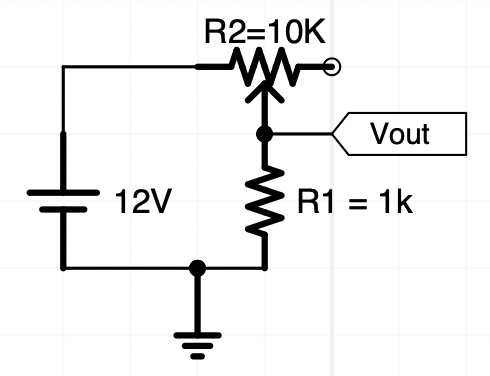

Fig. 1. Variable DC voltage source. 

What's the ouput voltage? 

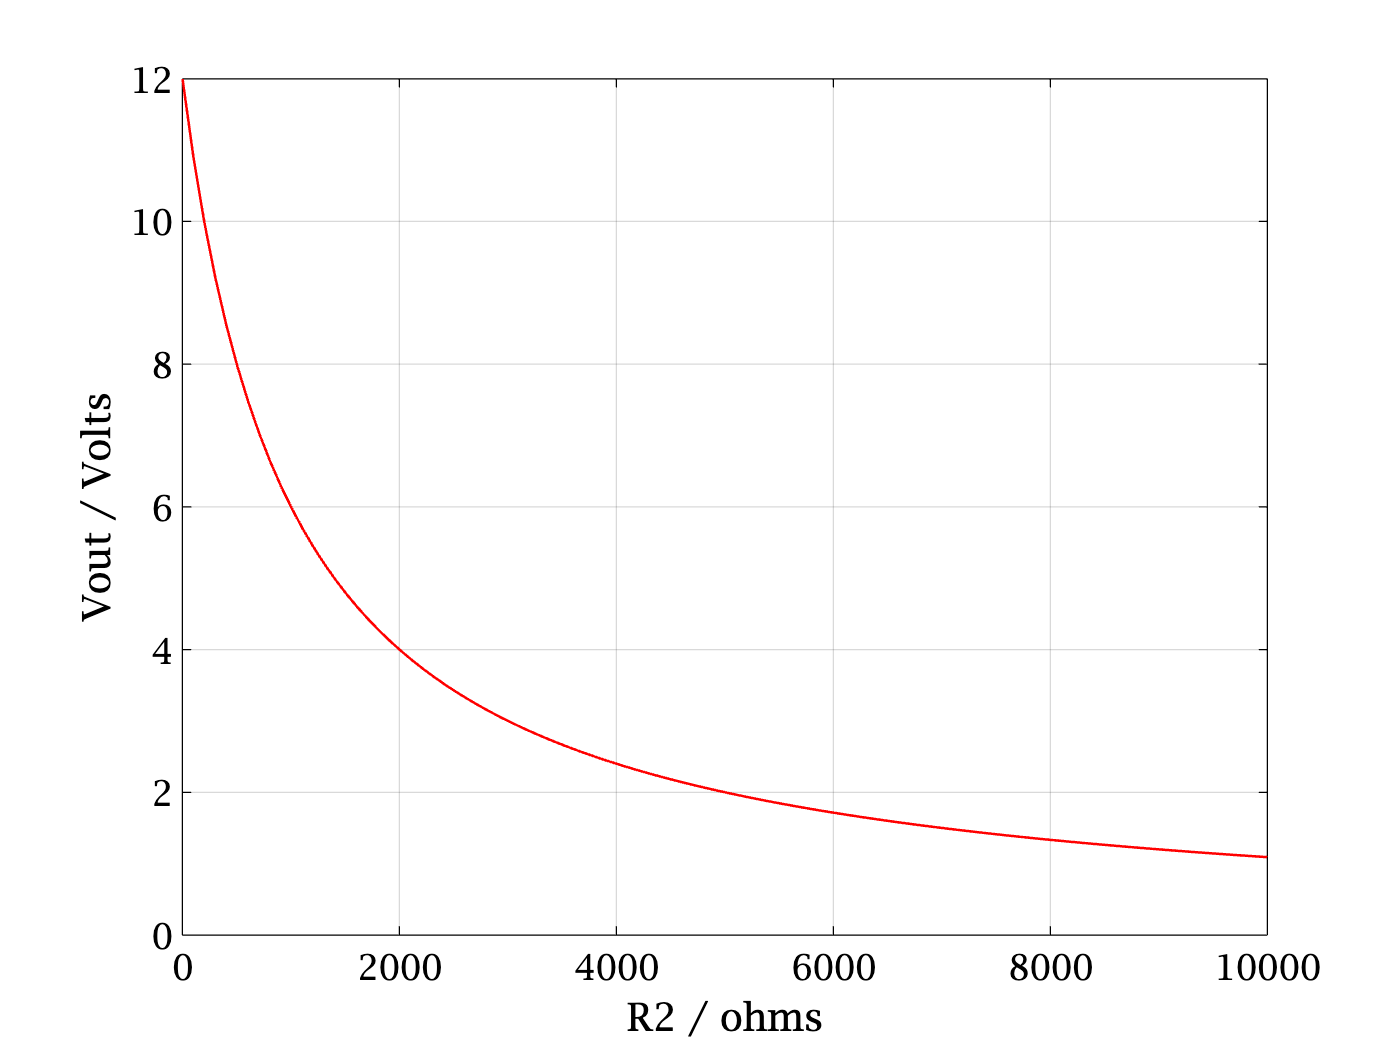

Vin = 12; 
R1 = 1e3;
R2 = linspace(0,1e4)';
Vout = Vin * R1 ./ (R1+R2);
plot(R2, Vout); 
xlabel('R2 / ohms'); ylabel('Vout / Volts')
grid;

From an ergonomic perspective, the voltage changes from 12 to 4V turning R2 just 1/5 of its rotation, and the last 1/2 of rotation changes the voltage from ~2V to 

min(Vout)

ans = 1.0909

The nonlinearity makes it hard to adjust. What if we connect a load resistor, Rl to the output and draw some current? Rl is in parallel with R1, which changes Vout: 

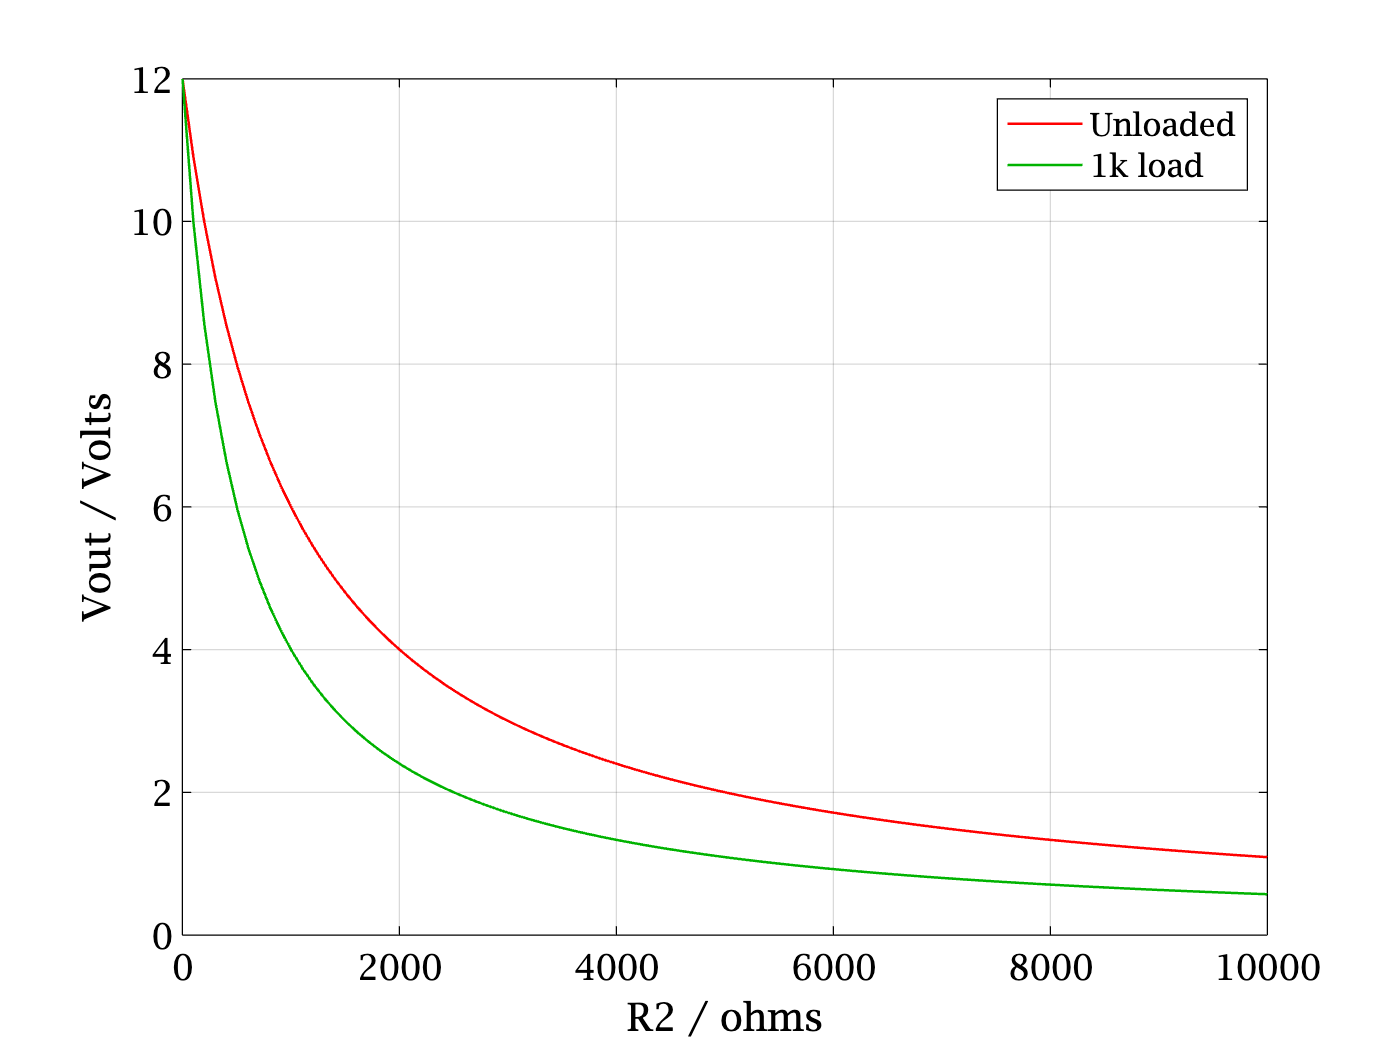

Rl = 1e3; % explore other values
Rparallel = R1 * Rl / (R1 + Rl);
VoutP = Vin * Rparallel ./ (Rparallel+R2);
plot(R2, [Vout VoutP]); 
xlabel('R2 / ohms'); ylabel('Vout / Volts')
legend('Unloaded','1k load')
grid;

The big change output voltage with load means the equivalent Rthevenin of this power supply is large. We can compute Rthevenin from these two curves, and we wrote a function to do this: 

In this case, we have 100 Vth and Vl values, will rthevenin work for vectors? You can try it ... look at the size of the result. 

The problem is the division of a vector by a vector has to be done "pointwise", i.e., replace / with ./:

Now

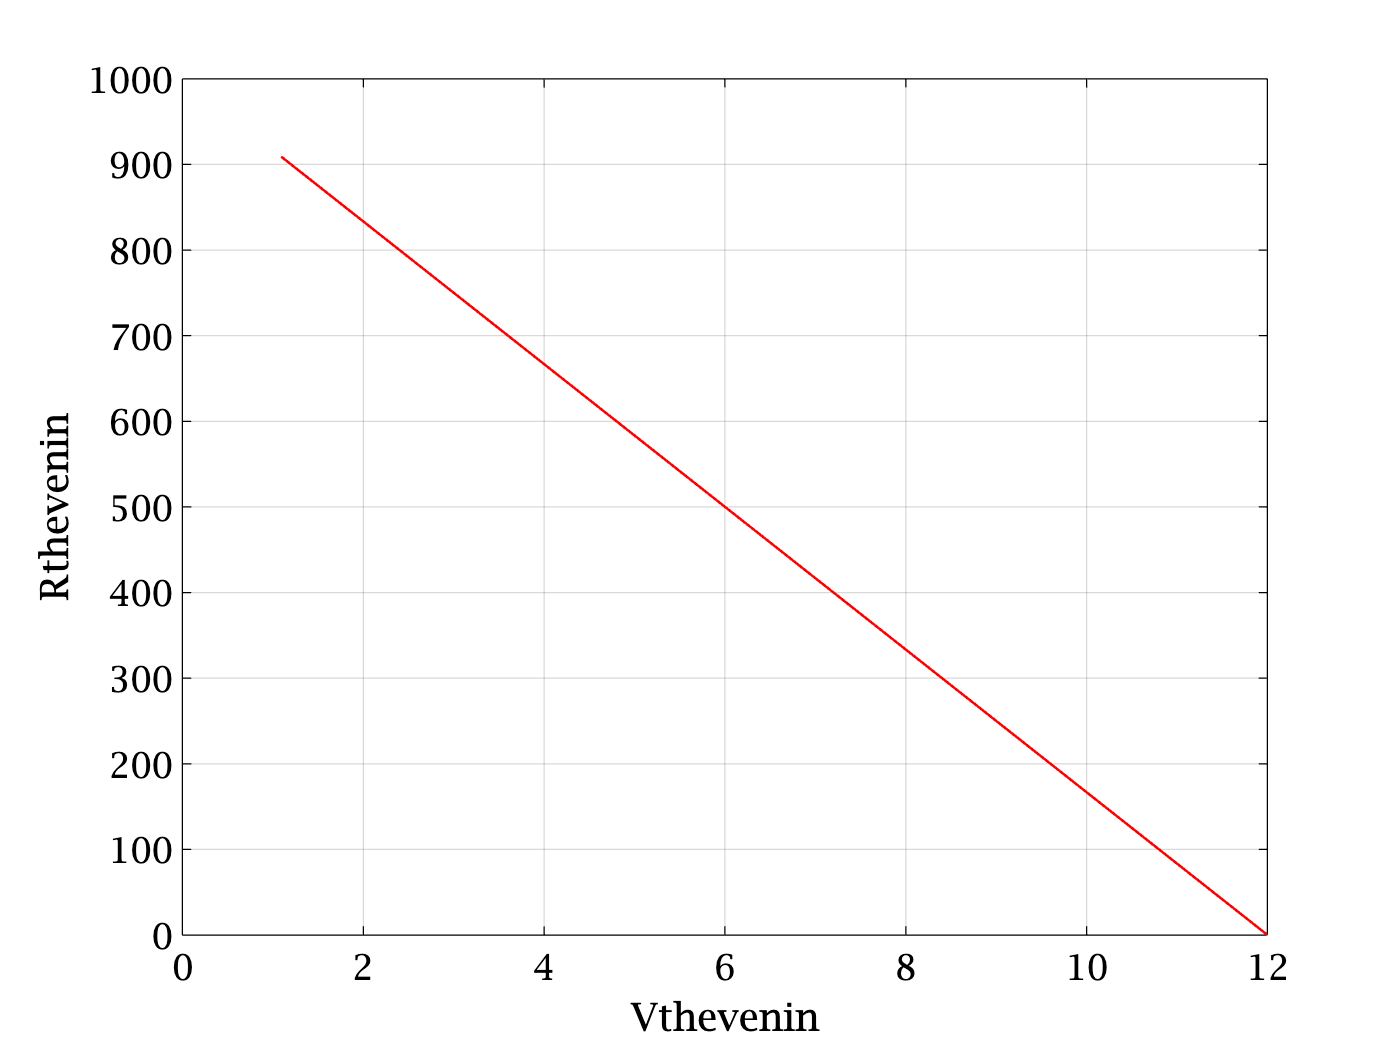

Rthevenin = rthevenin(Vout, VoutP, Rl);
plot(Vout, Rthevenin)
xlabel('Vthevenin'); ylabel('Rthevenin'); grid

Only at 12V (where R2 = 0) is Rth small, and thus the power supply will put out a constant voltage independent of Rload. 

Energy usage

Unrecognized function or variable 'safd'.